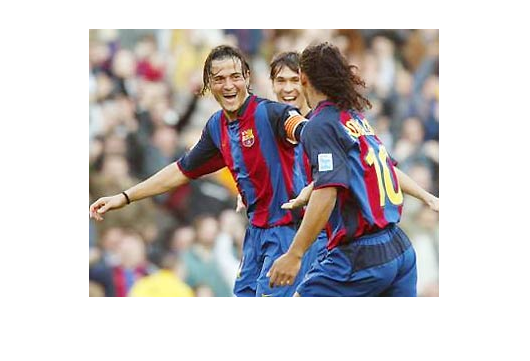

im = imread('model.jpg');
imshow(im);

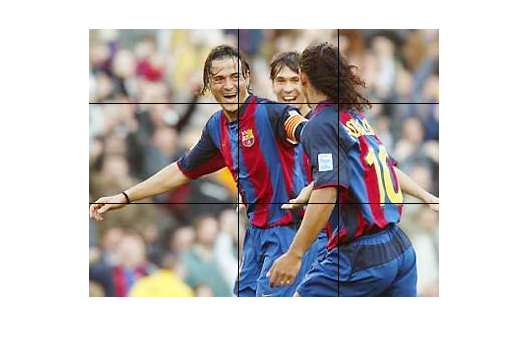


model = zeros(1, 65);
im(:, 150, :) = 0;
im(:, 250, :) = 0;
im(75, :, :) = 0;
im(175, :, :) = 0;
imshow(im);


r = im(:,:,1);
g = im(:,:,2);
b = im(:,:,3);

I = double(r) + double(g) + double(b);
red = double(r)./I;
gre = double(g)./I;
blu = double(b)./I;
im = uint8(cat(3, red, gre, blu)*255);

r = im(:,:,1);
g = im(:,:,2);
b = im(:,:,3);

I = 1/3*(r+g+b)

I = 268×350 uint8 matrix
   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85
   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85
   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85
   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85  

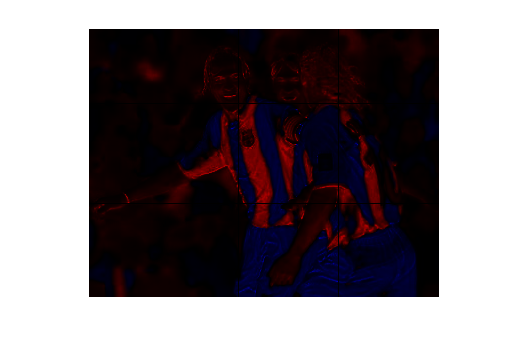

im = im - I;


im(:,:,2) = 0;
imshow(im,[]);

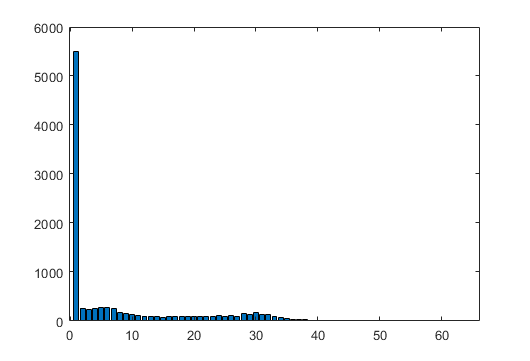

redHist = colorHistogram(75, 175, 150, 250, 1, im);

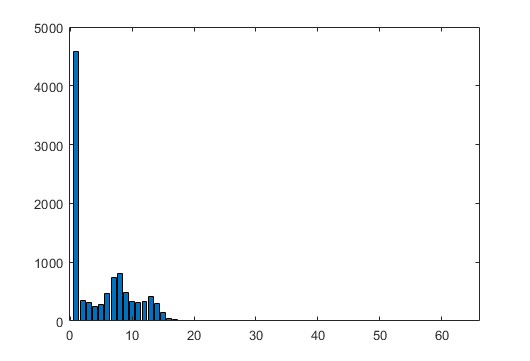

blueHist = colorHistogram(75, 175, 150, 250, 3, im);


distChiSq(redHist, redHist)

ans = 0

distChiSq(redHist, blueHist)

ans = 1.8225e+03

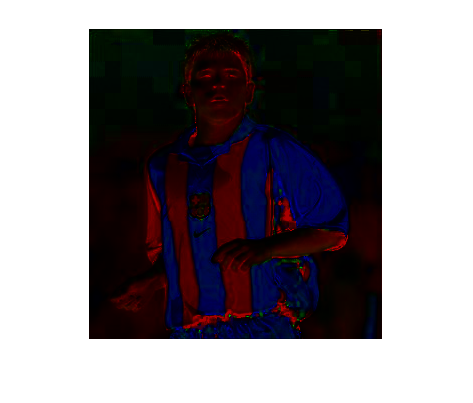

  Image with properties:

           CData: [310×293×3 uint8]
    CDataMapping: 'direct'

  Use get to show all properties



im = imread("proba1.jpg");

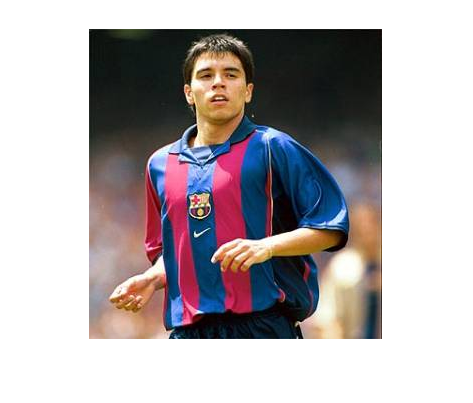

imshow("proba1.jpg");

cercaEquip(redHist, blueHist, imread('proba1.jpg'))

  Image with properties:

           CData: [310×293×3 uint8]
    CDataMapping: 'direct'

  Use get to show all properties



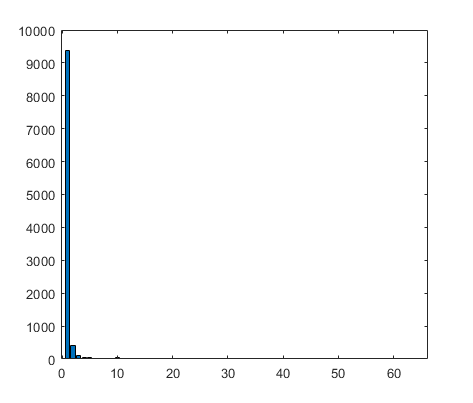

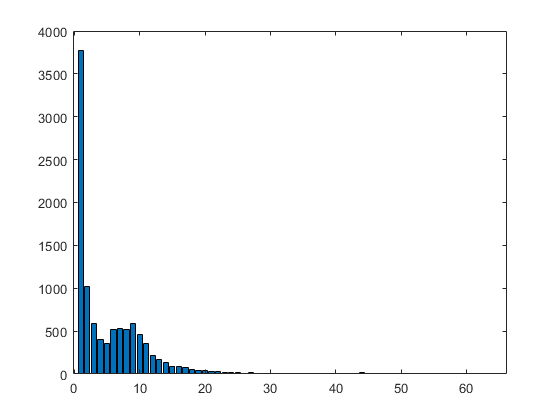

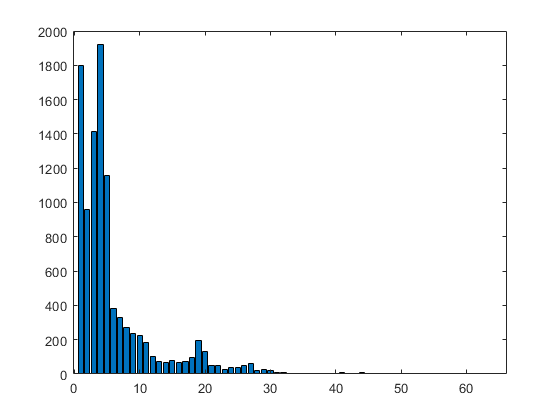

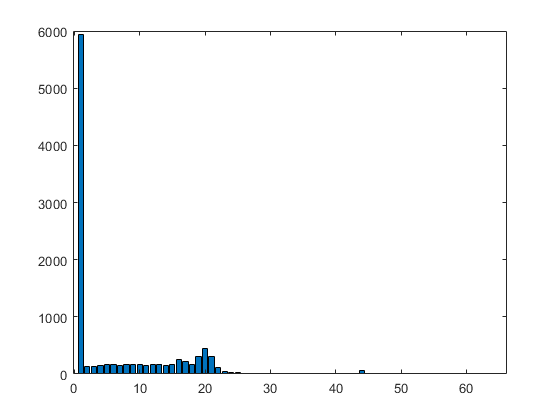

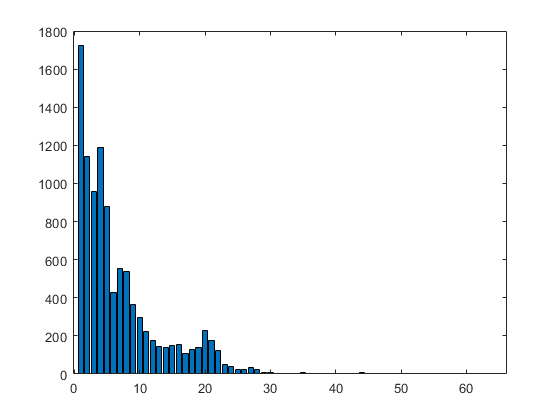

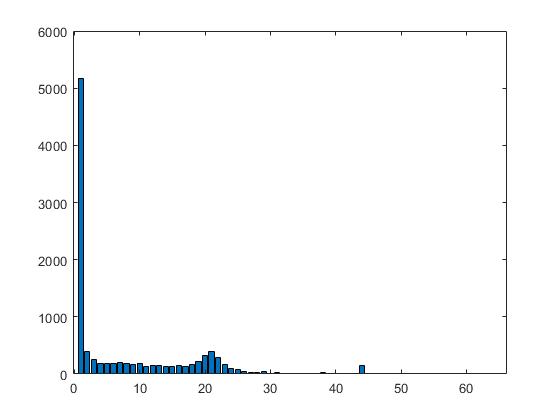

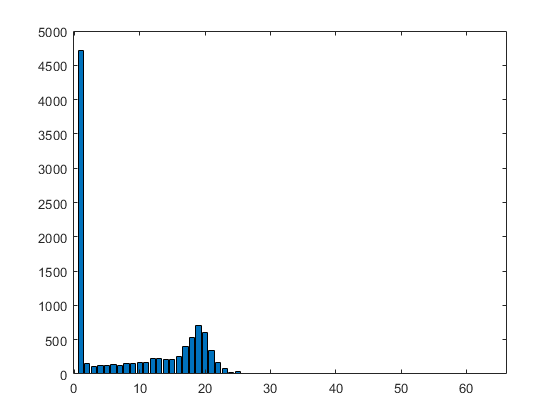

ans = logical
   0


function model = colorHistogram(xini, xfin, yini, yfin, color, im)

    model = zeros(1, 65);
    for i = [yini:yfin]
        for j = [xini:xfin]
            model(1, uint8(im(j, i, color)/4)+1) = model(1, uint8(im(j, i, color)/4)+1) + 1;
        end
    end
    bar(model);
end

function D = distChiSq( X, Y )

    m = size(X,1);  
    n = size(Y,1);
    mOnes = ones(1,m); 
    D = zeros(m,n);
    
    for i=1:n
      yi = Y(i,:);  
      yiRep = yi( mOnes, : );
      s = yiRep + X;    
      d = yiRep - X;
      D(:,i) = sum( d.^2 ./ (s+eps), 2 );
    end
    D = D/2;
end

function result = cercaEquip(redModelHist, blueModelHist, im)
    [x, y] = size(im(:,:,1));
    
    r = im(:,:,1);
    g = im(:,:,2);
    b = im(:,:,3);
    
    I = double(r) + double(g) + double(b);
    red = double(r)./I;
    gre = double(g)./I;
    blu = double(b)./I;
    
    im = uint8(cat(3, red, gre, blu)*255);
    
    display(imshow(im));
    
    stepX = (x/100)-1;
    stepY = (y/100)-1;
    
    i = 0;
    result = false;
    while i < stepX && ~result
        j = 0;
        while j < stepY && ~result
            redImgeHist = colorHistogram(i*100+1, (i+1)*100+1, j*100+1, (j+1)*100+1, 1, im);
            bar(redImgeHist);
            hold on
            bar(redModelHist);
            hold off;
            errR = distChiSq(redImgeHist, redModelHist);
            if (errR < 800)
                blueImgeHist = colorHistogram(i*100+1, (i+1)*100+1, j*100+1, (j+1)*100+1, 3, im);
                errB = distChiSq(blueImgeHist, blueModelHist);
                if ( errB < 800)
                    result = true;
                end
            end
            
            j = j + 1;
        end
        i = i + 1;
    end
    
end